clear

## Unit Cell

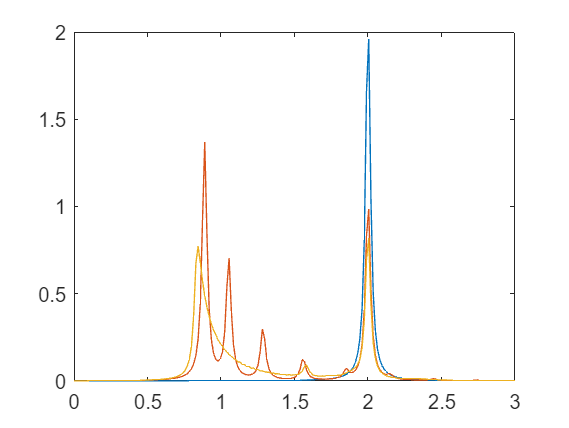

clear
a = 1;
a1 = [0;0]; a2 = [a*cosd(60);a*sind(60)]; a3 = a2+[a;0];
a4 = a3+[a*cosd(60);-a*sind(60)]; a5 = a4+[-a*cosd(60);-a*sind(60)];
a6 = a5-[a;0];

b = [a1 a2 a3 a4 a5 a6];
%plot(b(1,:),b(2,:),'k*')
%axis image
B = b;

for NN = [1 10 100] % Antal enhedsceller
add = [3*a;0];
for n = 1:NN-1
    B = [B b+add*n];
end
%plot(B(1,:),B(2,:),'k*')
%axis image

N = 6*NN;
for n = 1:N
    for m = 1:N
        d = B(:,n)-B(:,m);
        if abs(norm(d)-1)<1e-2
            H(n,m) = 1;
        else
            H(n,m) = 0;
        end
    end
end
[c,E] = eig(H);
E = diag(E);

freq = linspace(0,3,200);
alpha = zeros(1,length(freq));
for n = 1:N
    for m = 1:N
        if not(m==n) && E(n)>0 && E(m)<0
            pisx = 0;
            for k = 1:N
               pisx = pisx + c(k,n)*c(k,m)*B(1,k);
            end
            Enm = E(n)-E(m);
            alpha = alpha + abs(pisx)^2.*Enm./(Enm^2-(freq+1i*0.02).^2);
        end
    end
end
plot(freq,imag(alpha)./N)
hold on
end
hold off